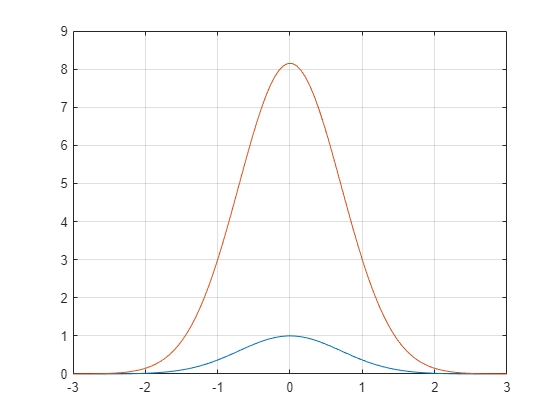

clear
t = linspace(-3,3,100);
y1 = exp(-t.*t);
y2 = 3*exp(1) * exp(-t.*t);
plot(t,y1)
grid on
hold on
plot(t, y2);

hold off

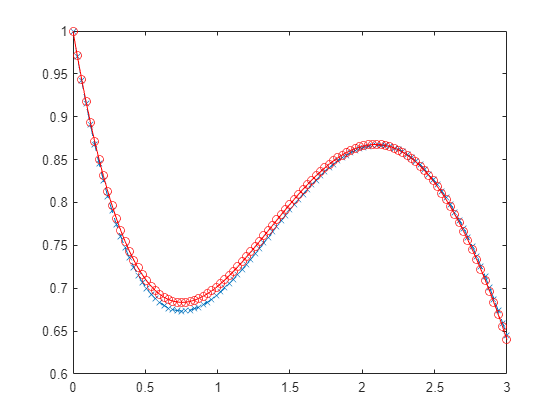

clf
clear
tspan = [0,3];
n = 100;
y1 = 1;
[t, y] = minEuler(@funkEx1, tspan, y1, n);
plot(t, y, 'x--');

ye = sin(t)/2 - cos(t)/2 + 3 * exp(-t)/2;
hold on
plot(t, ye, 'r-o')

clear
hold off

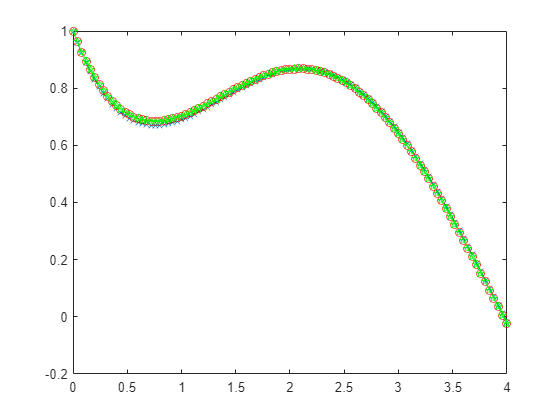

tspan = [0,4];
n = 100;
ybv = 1;
[~, y1] = minEuler(@funkEx2, tspan, ybv, n);
[~, y2] = minRK2(@funkEx2, tspan, ybv, n);
[t, y3] = minRK4(@funkEx2, tspan, ybv, n);
plot(t, y1, 'x--');

ye = sin(t)/2 - cos(t)/2 + 3 * exp(-t)/2;
hold on
plot(t, y2, 'r-o')
plot(t, y3, 'g-p')
hold off

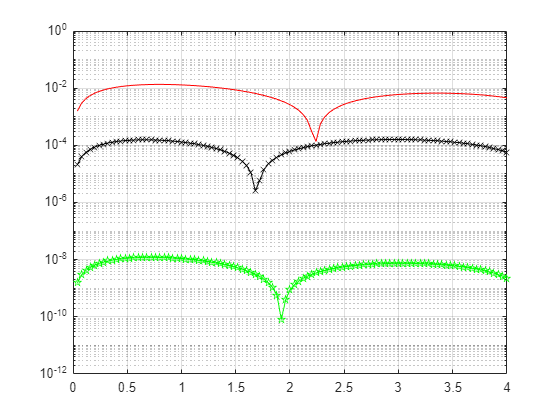

clf
semilogy(t, abs(y1-ye), 'r')
hold on
grid on
semilogy(t, abs(y2-ye), 'k-x')
semilogy(t, abs(y3-ye), 'g-p')

clear
clf
funkEx142(1,[1.3;3])

ans =     7.3000
   -3.4000


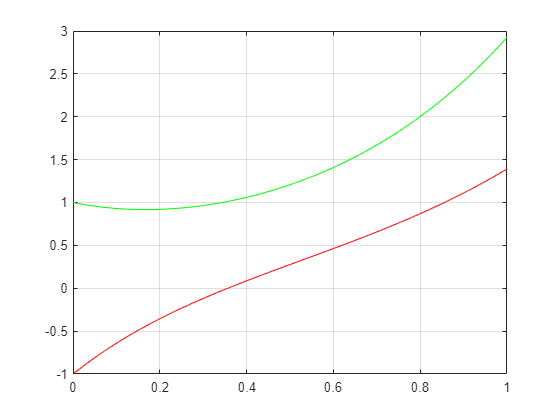

tspan = [0,1];
ybv = [1;-1];
n = 100;
[t, y] = minEuler(@funkEx142, tspan, ybv, n);
clf
plot(t, y(1,:), 'g')
hold on
plot(t,y(2,:), 'r')
grid on
hold off

clear
clf
funkEx143a(1,[1.3;3])

ans =     3.0000
    1.3100


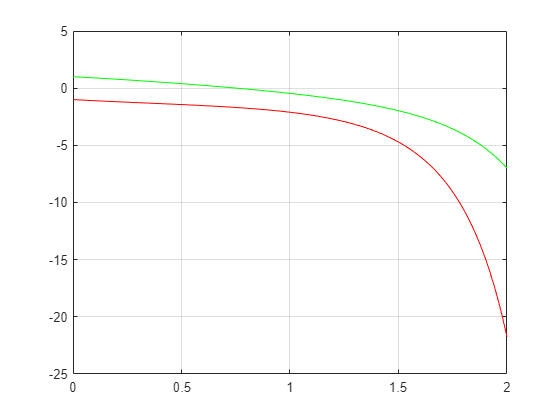

tspan = [0,2];
ybv = [1;-1];
n = 100;
[t, y] = minEuler(@funkEx143a, tspan, ybv, n);
clf
plot(t, y(1,:), 'g') % är y
hold on
plot(t,y(2,:), 'r') % är y'
grid on
hold off

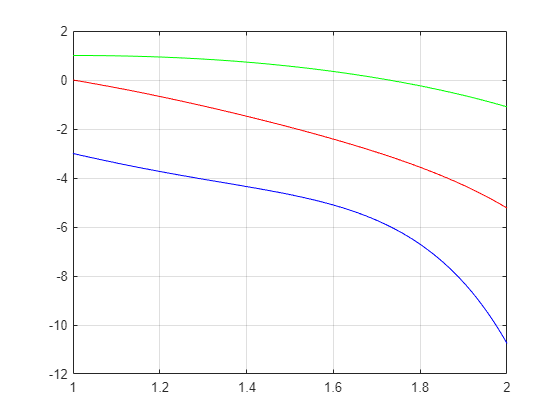

clear
clf
tspan = [1,2];
ybv = [1;0;-3];
n = 100;
[t, y] = minEuler(@funkEx143b, tspan, ybv, n);
clf
plot(t, y(1,:), 'g') % är y
hold on
plot(t,y(2,:), 'r') % är y'
plot(t,y(3,:), 'b') % är y''
grid on
hold off